clear

XYdom = [0,2; 0,1];

% Construct primal grid
x = Grid1DUnifPrimal(XYdom(1,:),101);
y = Grid1DUnifPrimal(XYdom(2,:),51);
grid = GridSpace2D(x,y);

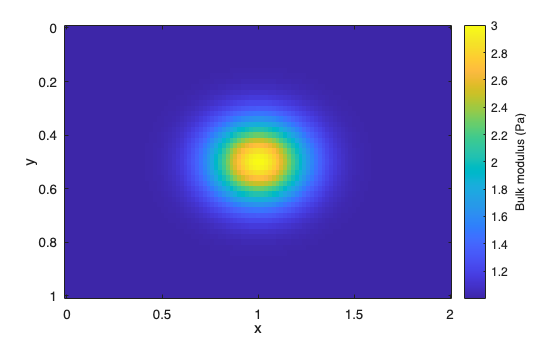

% Define medium
medium = AcousticMedium2D.gaussianPeak( ...
    KappaRange=[1,3], ...
    BetaRange=[2,5], ...
    Center=[1,0.5], ...
    Width=[0.25,0.15]);

% Sample onto staggered grids
[K,Bx,By] = sampleMedium2D(grid,medium);

% Visualize the sampled medium properties
figure
K.plot;

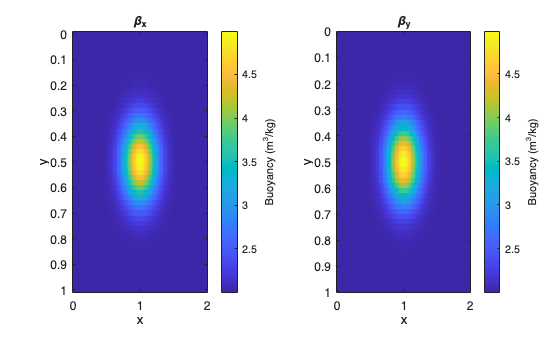


figure
tiledlayout(1,2);

nexttile
Bx.plot;
title("\beta_x")

nexttile
By.plot;
title("\beta_y")

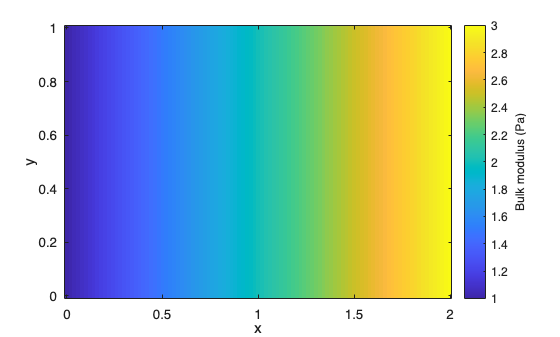

% Define medium
medium = AcousticMedium2D.linearX( ...
    KappaRange=[1,3], ...
    BetaRange =[2,5], ...
    Domain    = XYdom);

% Sample onto staggered grids
[K,Bx,By] = sampleMedium2D(grid,medium);


% Visualize the sampled medium properties
figure
K.plot;
ax = gca;
ax.YDir = "normal";

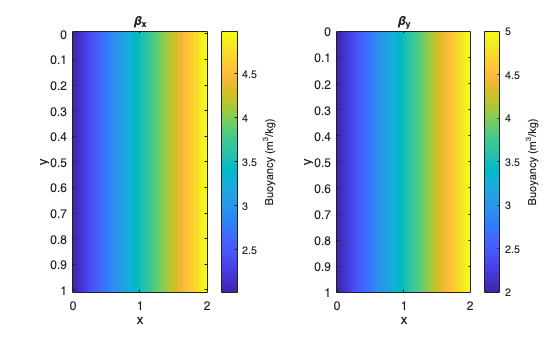


figure
tl = tiledlayout(1,2);

nexttile
Bx.plot;
title("\beta_x")

nexttile
By.plot;
title("\beta_y")

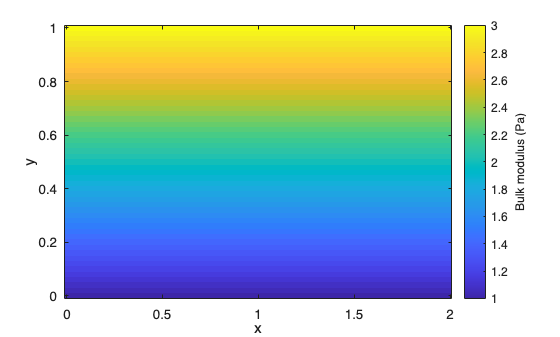

% Define medium
medium = AcousticMedium2D.linearY( ...
    KappaRange=[1,3], ...
    BetaRange =[2,5], ...
    Domain    = XYdom);

% Sample onto staggered grids
[K,Bx,By] = sampleMedium2D(grid,medium);


% Visualize the sampled medium properties
figure
K.plot;
ax = gca;
ax.YDir = "normal";

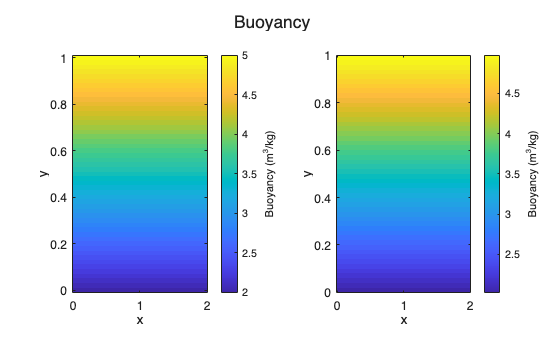


figure
tl = tiledlayout(1,2);
title(tl,"Buoyancy")

nexttile
Bx.plot;
ax = gca;
ax.YDir = "normal";

nexttile
By.plot;
ax = gca;
ax.YDir = "normal";

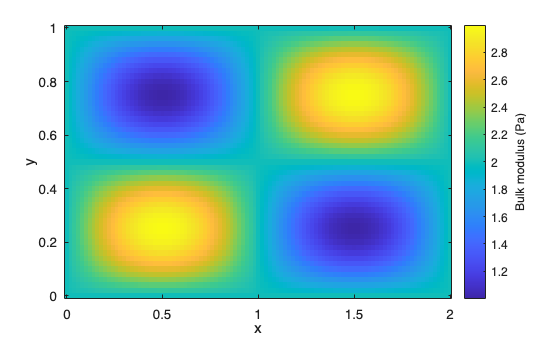

% Define medium
medium = AcousticMedium2D.smooth( ...
    KappaRange=[1,3], ...
    BetaRange =[2,5], ...
    Domain    = XYdom);

% Sample onto staggered grids
[K,Bx,By] = sampleMedium2D(grid,medium);


% Visualize the sampled medium properties
figure
K.plot;
ax = gca;
ax.YDir = "normal";

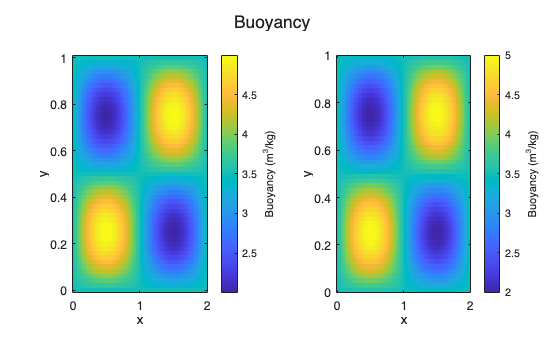


figure
tl = tiledlayout(1,2);
title(tl,"Buoyancy")

nexttile
Bx.plot;
ax = gca;
ax.YDir = "normal";

nexttile
By.plot;
ax = gca;
ax.YDir = "normal";

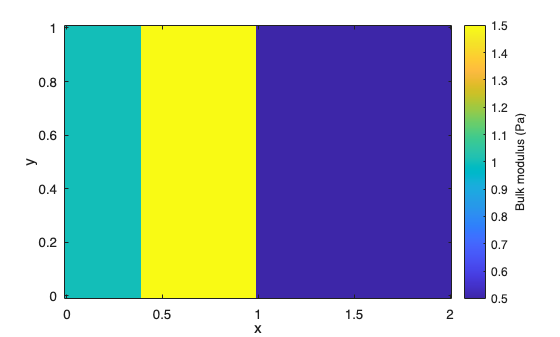

% Define medium
medium = AcousticMedium2D.layeredX( ...
    KappaValues   = [1,1.5,0.5], ...
    BetaValues    = [2,4,1], ...
    RelativeWidths= [0.2,0.3,0.5], ...
    Domain        = XYdom);

% Sample onto staggered grids
[K,Bx,By] = sampleMedium2D(grid,medium);

% Visualize the sampled medium properties
figure
K.plot;
ax = gca;
ax.YDir = "normal";

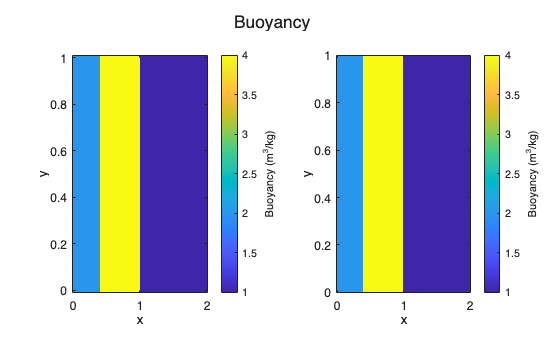


figure
tl = tiledlayout(1,2);
title(tl,"Buoyancy")

nexttile
Bx.plot;
ax = gca;
ax.YDir = "normal";

nexttile
By.plot;
ax = gca;
ax.YDir = "normal";

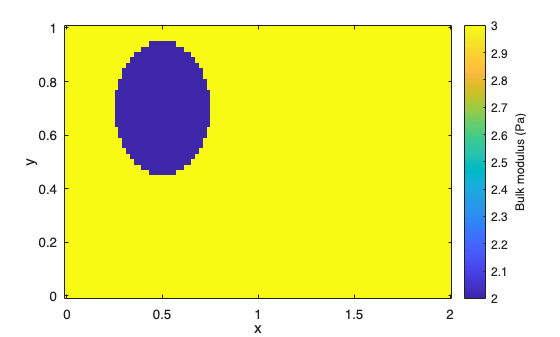

% Define medium
medium = AcousticMedium2D.circular( ...
    KappaInside  = 2, ...
    KappaOutside = 3, ...
    BetaInside   = 1, ...
    BetaOutside  = 4, ...
    Center       = [0.5,0.7], ...
    Radius       = 0.25);

% Sample onto staggered grids
[K,Bx,By] = sampleMedium2D(grid,medium);

% Visualize the sampled medium properties
figure
K.plot;
ax = gca;
ax.YDir = "normal";

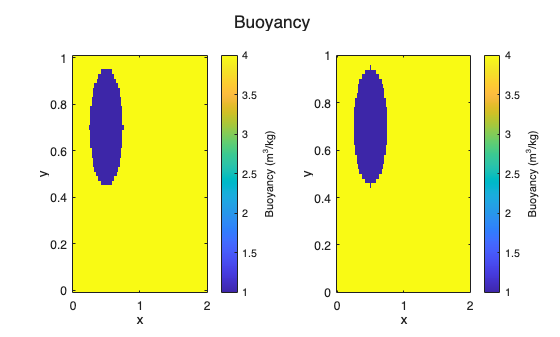


figure
tl = tiledlayout(1,2);
title(tl,"Buoyancy")

nexttile
Bx.plot;
ax = gca;
ax.YDir = "normal";

nexttile
By.plot;
ax = gca;
ax.YDir = "normal";

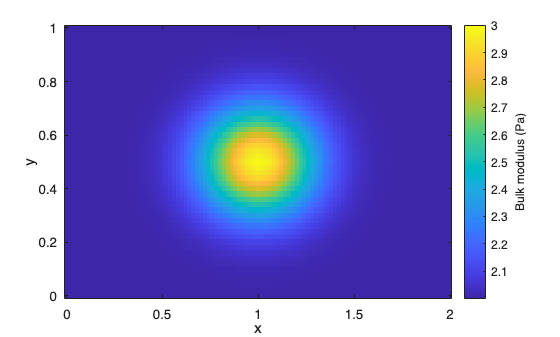

xData = linspace(0,2,41);
yData = linspace(0,1,21);

% ndgrid gives arrays with size [numel(xData),numel(yData)]
[XData,YData] = ndgrid(xData,yData);
kappaData = 2 + ...
    exp(-((XData-1)/0.3).^2-((YData-0.5)/0.2).^2);
betaData = 3 + ...
    0.5*sin(pi*XData).*sin(2*pi*YData);

% Construct the continuous medium
medium = AcousticMedium2D.tabulated( ...
    XCoordinates=xData, ...
    YCoordinates=yData, ...
    KappaValues=kappaData, ...
    BetaValues=betaData, ...
    Method="linear", ...
    ExtrapolationMethod="none");

% Sample onto staggered grids
[K,Bx,By,C] = sampleMedium2D(grid,medium);

% Visualize the sampled medium properties
figure
K.plot;
ax = gca;
ax.YDir = "normal";

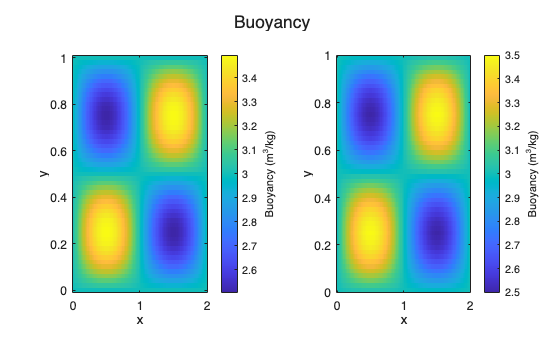


figure
tl = tiledlayout(1,2);
title(tl,"Buoyancy")

nexttile
Bx.plot;
ax = gca;
ax.YDir = "normal";

nexttile
By.plot;
ax = gca;
ax.YDir = "normal";

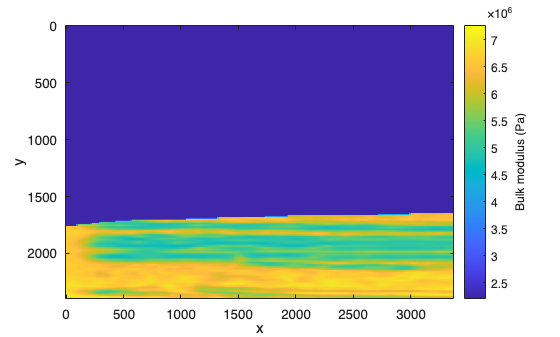

data = load("salt2D_data.mat");

medium = AcousticMedium2D.tabulated( ...
    XCoordinates=data.xData, ...
    YCoordinates=data.yData, ...
    KappaValues=data.kappaData, ...
    BetaValues=data.betaData);

% Construct primal grid
x = Grid1DUnifPrimal(data.xDom*0.05,251);
y = Grid1DUnifPrimal(data.yDom*0.2,401);
grid = GridSpace2D(x,y);

% Sample onto staggered grids
[K,Bx,By] = sampleMedium2D(grid,medium);

% Visualize the sampled medium properties
figure
K.plot;

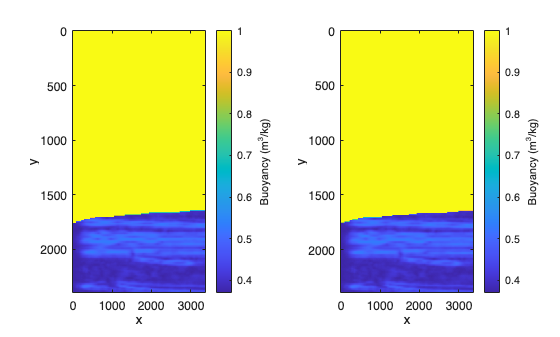

figure
tl = tiledlayout(1,2);

nexttile
Bx.plot;

nexttile
By.plot;